# **Runge Kutta 4 en Sistema de Ecuaciones Diferenciales**

Diego Alejandro Espejo López A01638341

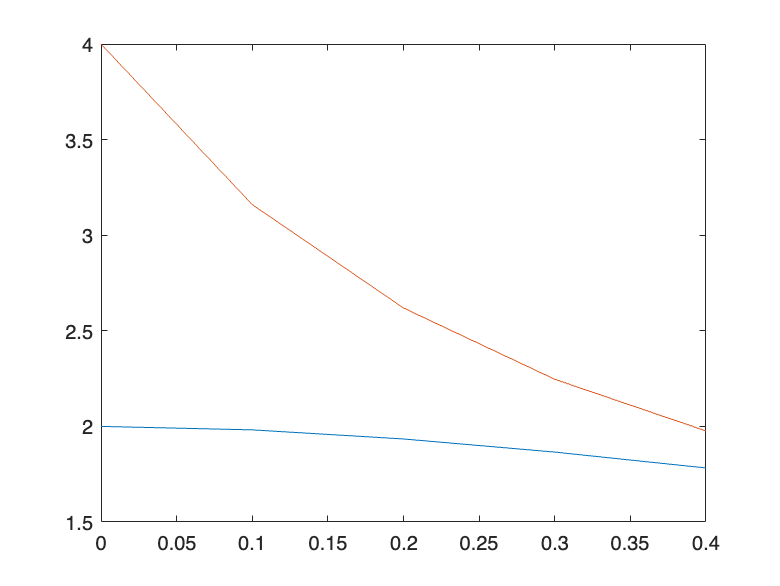

clear; clc;

% Variables
ti = 0;
yi = 2;
zi = 4;
h = 0.1;
tf = 0.4;
n = (tf - ti) / h;

% Hacemos los vectores
t = zeros(1, n+1);
y = zeros(1, n+1);
z = zeros(1, n+1);
t(1) = ti;
y(1) = yi; 
z(1) = zi;

% Funciones
f1 = @(t,y,z) (-2*y + 4*exp(-t));
f2 = @(t,y,z) (-(y*z^2) / 3);

for i=1:n
    t(i+1) = t(i) + h;

    % K1
    k11 = f1(t(i), y(i), z(i));
    k12 = f2(t(i), y(i), z(i));

    % K2
    k21 = f1(t(i) + h/2, y(i) + (h/2)*k11, z(i) + (h/2)*k12);
    k22 = f2(t(i) + h/2, y(i) + (h/2)*k11, z(i) + (h/2)*k12);

    % K3
    k31 = f1(t(i) + h/2, y(i) + k21*(h/2), z(i) + k22*(h/2));
    k32 = f2(t(i) + h/2, y(i) + k21*(h/2), z(i) + k22*(h/2));

    % K4
    k41 = f1(t(i) + h, y(i) + h*k31, z(i) + h*k32);
    k42 = f2(t(i) + h, y(i) + h*k31, z(i) + h*k32);

    y(i+1) = y(i) + (h/6)*(k11 + 2*k21 + 2*k31 + k41);
    z(i+1) = z(i) + (h/6)*(k12 + 2*k22 + 2*k32 + k42);
end

plot(t,y,t,z)